# Step Size Expectation

Script to compute the statistical expectation of the step size 

dimen = 4096; 
pop_size = 40;
weights = rankweight(pop_size,pop_size/2);
mu = 0.5;
basis_norm = 100;

grad_vect = randn(1, dimen);
score_lin = @(x) x * grad_vect';

Compute the expected gradient norm! 

score_fun = score_lin;
basis_vec = zeros(1, dimen);
basis_vec(1) = basis_norm; 
ExpectStepSize = sqrt(dimen * sum(weights.^2)) * mu;
disp(ExpectStepSize)

    9.5154



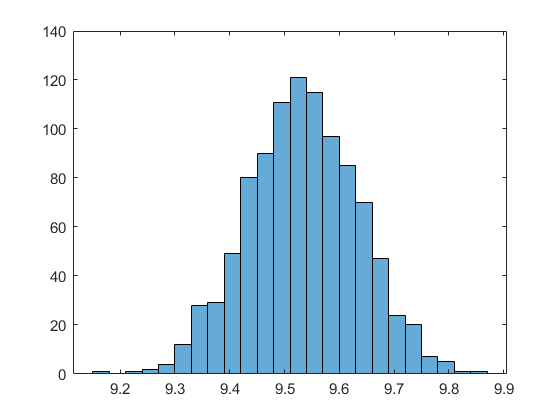

gradnorm=zeros(1,1000);
for i = 1:1000
tang_codes = mu * randn(pop_size, dimen);
f_basis = score_fun(basis_vec);
f_exp = score_fun(basis_vec + tang_codes);
[sorted_f, sort_arg] = sort(f_exp);
hagrad = weights * tang_codes(sort_arg, :);
gradnorm(i) = norm(hagrad);
end
figure, clf, histogram(gradnorm)

mu = 0.5;
basis_vec = zeros(1, dimen);
basis_vec(1) = basis_norm; 
tang_codes = mu * randn(4000, dimen);
new_codes = basis_vec+tang_codes;
newnorms = sqrt(sum(new_codes.^2,2));
figure(5), clf, histogram(newnorms)